%Spline cubico base: Cal
X = [-1 1 3 5]
Y = [3 1 -3 -4]
[Ac_base, B] = sistemabase(X,Y);
[Ac_natural, B] = sistemanatural(X,Y);
S=csnatural(X,Y)

%Spline cubico extrapolado
[Ac_extrapolado, B] = sistemaextrapolado(X,Y)

%Spline cubico con terminacion parabolica
[Ac_parabolica, B] = sistemaparabolico(X,Y)


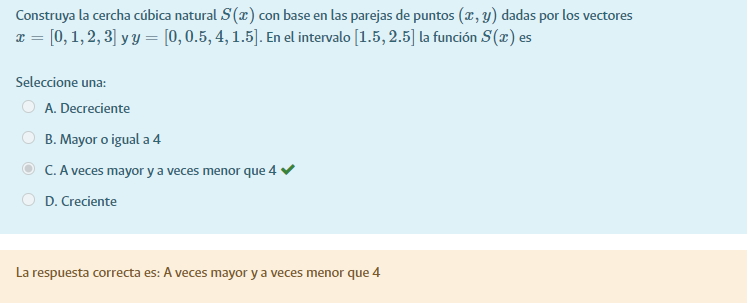

X = [0 1 2 3]
Y = [0 0.5 4 1.5]
S=csnatural(X,Y)
GraficaCercha(X,Y,S)%Grafica del Spline cubico
hold on
yline(4)
axis([1.5 2.5 2 6])
%Rta la c

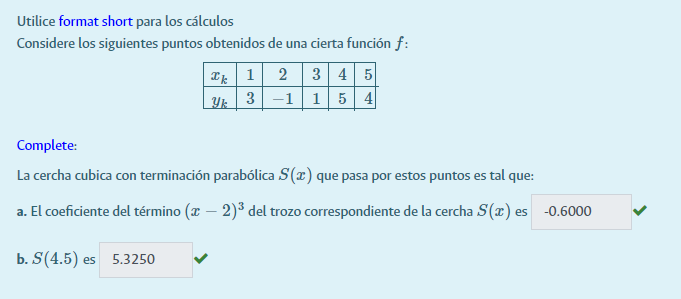

format short 
X = [1 2 3 4 5]
Y = [3 -1 1 5 4]
%  EL CONSTANTE ES EL MISMO DE TERMINACION PARABOLICA
S=csconstante(X,Y) % El valor pedido es -0.6

polyval(S(4,:),4.5-4) % La estructura del spline es S es la matriz con las filas
% de cada valor x_nodo. Para este caso, 4.5 es el ultimo tramo del spline y

X =      1     2     3     4     5


% en este se ha de evaluar (punto-nodo_spline).

Y =      3    -1     1     5     4


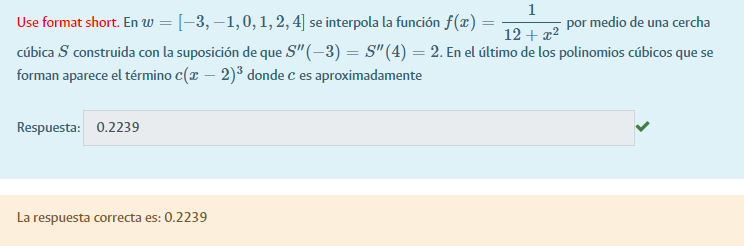

format short 

S =          0    3.3000   -7.3000    3.0000
   -0.6000    3.3000   -0.7000   -1.0000
   -1.6000    1.5000    4.1000    1.0000
         0   -3.3000    2.3000    5.0000


f = @(x) 1./(12+x.^2);
X = [-3 -1 0 1 2 4];

ans =          0   -3.3000    2.3000    5.0000


Y = f(X);
b=2, a=b
S=csconocido(X,Y,a,b) % En a y b se colocan los valores extermos de la sda
% derivada

b = 2

a = 2

S =    -0.2246    1.0000   -1.0869    0.0476
    0.1363   -0.3476    0.2178    0.0769
    0.0012    0.0611   -0.0687    0.0833
   -0.1361    0.0646    0.0570    0.0769
    0.2239   -0.3436   -0.2219    0.0625